**Demographic-Economic System Analysis:**

This script simulates the evolution of population age structure and analyzes the sustainability of the PAYG pension scheme.

clear; clc; close all;

Load Parameters:

% We fetch parameters from our setup file
P = get_parameters();

Check parameters (Optional display):

disp("Running simulation with Pension Replacement Rate (Beta): " + P.beta);

Running simulation with Pension Replacement Rate (Beta): 0.45


Setup Simulation:

Data from Austria: 

[https://www.statistik.at/statistiken/bevoelkerung-und-soziales/bevoelkerung/bevoelkerungsstand/bevoelkerung-nach-alter/geschlecht](https://www.statistik.at/statistiken/bevoelkerung-und-soziales/bevoelkerung/bevoelkerungsstand/bevoelkerung-nach-alter/geschlecht) 

% Initial Population Stocks
Y0   = [P.A_Y0; P.A_M0; P.A_O0];

Run Solver:

% We use ode45 to solve the system defined in 'model_dynamics.mlx'
[t, Y] = ode45(@(t,y) model_dynamics(t, y, P), P.tspan, Y0);

% --- Calculation of Equilibrium (Steady State) ---
t_final = P.tspan(2); 

% In steady state, Ay/Am and Ao/Am are constant based on transition rates
y_eq_ratio = 1 / (P.lam_Y * (P.T_M_base + P.dyn_retire.speed * t_final));
o_eq_ratio = (1 / (P.lam_M)) / (P.T_O_base + P.dyn_aging.speed * t_final); 

% numerical solver for the worker population Am
% where births + migration = deaths/exits
eq_resid = @(Am_val) model_dynamics(t_final, [Am_val*y_eq_ratio; Am_val; Am_val*o_eq_ratio], P);

% Trying to find Am where the middle derivative (dAm) is zero
lower_bound = 0;
upper_bound = 1e8; % 100 Millionen als Maximum
[Am_ss, ~, exitflag] = fminbnd(@(Am_val) norm(eq_resid(Am_val)), lower_bound, upper_bound);

if exitflag > 0
    Y_eq = [Am_ss * y_eq_ratio; Am_ss; Am_ss * o_eq_ratio];
    
    % Calculate economic values
    y_r = Y_eq(1)/Y_eq(2);
    o_r = Y_eq(3)/Y_eq(2);
    tau_eq = (P.alpha * y_r + P.beta * o_r) / (1 + P.alpha * y_r + P.beta * o_r);
    n_eq = P.psi * (1 - tau_eq);

    fprintf('\n========================================\n');
    fprintf('STEADY STATE RESULTS (Calculated via fminsearch)\n');
    fprintf('========================================\n');
    fprintf('Youth Population (Ay):   %.0f\n', Y_eq(1));
    fprintf('Worker Population (Am):  %.0f\n', Y_eq(2));
    fprintf('Retired Population (Ao): %.0f\n', Y_eq(3));
    fprintf('----------------------------------------\n');
    fprintf('Steady State Tax Rate:   %.2f%%\n', tau_eq * 100);
    fprintf('Steady State Fertility:  %.4f\n', n_eq);
    fprintf('========================================\n\n');
else
    fprintf('\n[Warning] Could not converge to steady state.\n');
end

STEADY STATE RESULTS (Calculated via fminsearch)


Youth Population (Ay):   0


Worker Population (Am):  0


Retired Population (Ao): 0


----------------------------------------


Steady State Tax Rate:   48.28%


Steady State Fertility:  0.0112


Post-Processing:

% Reconstruct algebraic variables for analysis
Ay_hist = Y(:,1);
Am_hist = Y(:,2);
Ao_hist = Y(:,3);

% Avoid division by zero
Am_hist(Am_hist==0) = 1;

y_hist = Ay_hist ./ Am_hist;
o_hist = Ao_hist ./ Am_hist;

Recalculate Tax ($\tau$) and Fertility ($n$) history:

numerator   = P.alpha .* y_hist + P.beta .* o_hist;
denominator = 1 + numerator;
tau_hist    = numerator ./ denominator;

n_hist      = P.psi .* (1 - tau_hist);

Visualization:

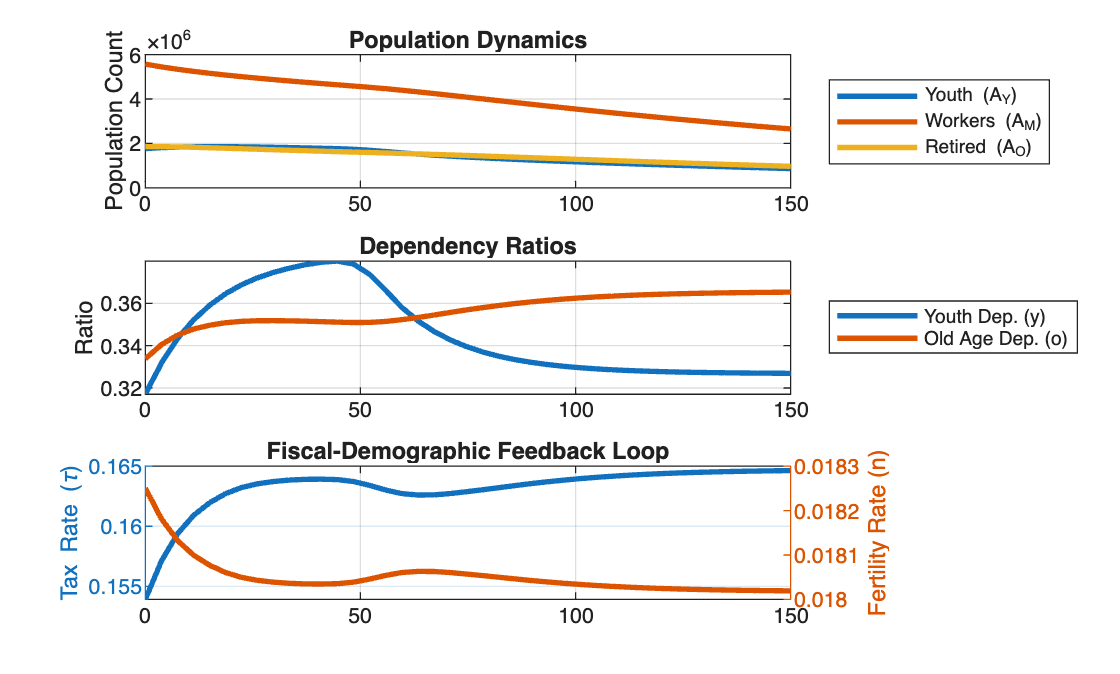

% Call the visualization function
visualize_results(t, Y, tau_hist, n_hist);